filelist = ["data_04-Mar-2025_10.mat","data_04-Mar-2025_14-46-39.mat","data_04-Mar-2025_14-48-35.mat","data_04-Mar-2025_14-49-36.mat","data_04-Mar-2025_15-02-19.mat","data_04-Mar-2025_15-04-28.mat","data_04-Mar-2025_15-06-09.mat","data_04-Mar-2025_15-07-04.mat","data_04-Mar-2025_15-13-13.mat","data_04-Mar-2025_15-16-08.mat","data_04-Mar-2025_15-27-48.mat","data_04-Mar-2025_15-29-27.mat","data_04-Mar-2025_15-30-56.mat","data_04-Mar-2025_15-31-20.mat","data_04-Mar-2025_15-33-26.mat","data_04-Mar-2025_15-34-00.mat","data_04-Mar-2025_15-37-14.mat","data_04-Mar-2025_15-39-43.mat","data_04-Mar-2025_15-42-28.mat","data_04-Mar-2025_15-43-46.mat","data_04-Mar-2025_15-47-42.mat","data_04-Mar-2025_15-49-10.mat","data_04-Mar-2025_15-51-30.mat","data_04-Mar-2025_15-52-22.mat","data_04-Mar-2025_15-54-09.mat","data_04-Mar-2025_15-57-04.mat","data_04-Mar-2025_16-08-14.mat","data_04-Mar-2025_16-11-22.mat","data_04-Mar-2025_16-14-18.mat","data_04-Mar-2025_16-16-56.mat","data_04-Mar-2025_16-18-18.mat","data_04-Mar-2025_16-21-30.mat","data_04-Mar-2025_16-24-24.mat","data_04-Mar-2025_16-29-52.mat","data_04-Mar-2025_16-55-40.mat","data_04-Mar-2025_17-24-37.mat","data_04-Mar-2025_17-40-31.mat","data_04-Mar-2025_17-41-21.mat","data_04-Mar-2025_17-43-22.mat","data_04-Mar-2025_17-50-09.mat","data_04-Mar-2025_17-51-54.mat","data_04-Mar-2025_17-54-59.mat","data_04-Mar-2025_17-57-30.mat","data_04-Mar-2025_17-57-53.mat","data_04-Mar-2025_18-00-51.mat","data_04-Mar-2025_18-01-13.mat","data_04-Mar-2025_18-03-09.mat","data_04-Mar-2025_18-06-22.mat","data_04-Mar-2025_18-07-09.mat","data_04-Mar-2025_18-09-15.mat","data_04-Mar-2025_18-10-36.mat","data_04-Mar-2025_18-11-39.mat","data_04-Mar-2025_18-12-13.mat","data_04-Mar-2025_18-13-24.mat","data_04-Mar-2025_18-14-40.mat","data_04-Mar-2025_18-15-39.mat","data_04-Mar-2025_18-16-46.mat","data_04-Mar-2025_18-17-52.mat","data_04-Mar-2025_18-18-49.mat"];

n_exp = 54;
n_exp = find(filelist == "data_04-Mar-2025_17-41-21.mat" )

n_exp = 38

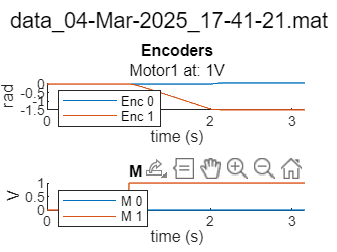

ans = logical
   1


load("lab1/data/"+filelist(n_exp),"data")
%plot(data(1,:),data(2,:))
smartPlotEncVoltage(data,filelist(n_exp),false)


Ts = data(1,2)-data(1,1) % get sampling period

Ts = 0.0020

t = data(1,:);
x = data(3,:);
% fs = 1/Ts
% fnyq = fs/2
% fpb = 40                   % 40 Hz bassband
% b = fir1(1, fpb/fnyq, 'low'); % low freq filter
% y = filter(b,1,x);
% 
% figure
% plot(t,x,t,y)


pole1 = 80*1;
pole2 = 80*5;
derivAndLowPass = zpk([0],[-pole1 -pole2],(pole1 *pole2))


derivAndLowPass =
 
     32000 s
  --------------
  (s+80) (s+400)
 
Continuous-time zero/pole/gain model.
Model Properties


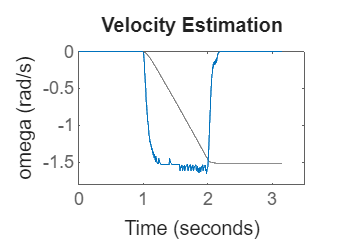


% bode(derivAndLowPass)
figure;
lsimplot(derivAndLowPass,x(1:end)*pi/2048,t(1:end));
title("Velocity Estimation");
ylabel("omega (rad/s)");

## Calculations

omega_l = 1.57;
omega_m = 70*omega_l;
V = 1;
R = 2.6;
k = 7.68e-3;
E = k * omega_m

E = 0.8440

I = (V-E)/R

I = 0.0600

torque = I * k

torque = 4.6071e-04

beta = torque/omega_m

beta = 4.1920e-06